clc; close all; clearvars; close all;
colormap jet
GrainInitialNumber = 1000

GrainInitialNumber = 100

Trimming_Upper_Limit = 0.8;
Trimming_Lower_limit = 0.2;
map = Map(1e-4, 1e-4, 2200, 4400); % x width 1e-4 m, y width 1e-4, velocity limit: 2400-3200
map=map.setNumberOfDots(GrainInitialNumber); % number of grain (uncropped) is 900
seed = randi(pow2(2,30));
map= map.defineCentroids(seed);
map = map.createVoronoin();
hold on
for i = 1:length(map.centroid_cells)
    if all(map.centroid_cells{i}~=1) % If at least one of the indices is 1,
    % then it is an open region and we can't
    % patch that.
    P = patch(map.centroid_vertices(map.centroid_cells{i},1),map.centroid_vertices(map.centroid_cells{i},2), i); % use colour i.
    P.EdgeColor = 'none'; % colour the patches
    end
end
xlim([Trimming_Lower_limit Trimming_Upper_Limit])
ylim([Trimming_Lower_limit Trimming_Upper_Limit])
axis off
saveas(P,'voronoi.png');
Remaining_Centroid_Mask = (map.centroid_x >= 0.2 & map.centroid_x<=0.8) & (map.centroid_y >= 0.2 & map.centroid_y<=0.8);
number_of_centroids = size(find(Remaining_Centroid_Mask == 1));
fprintf("[Info] Grain Number: %d", number_of_centroids(1));

[Info] Grain Number: 35

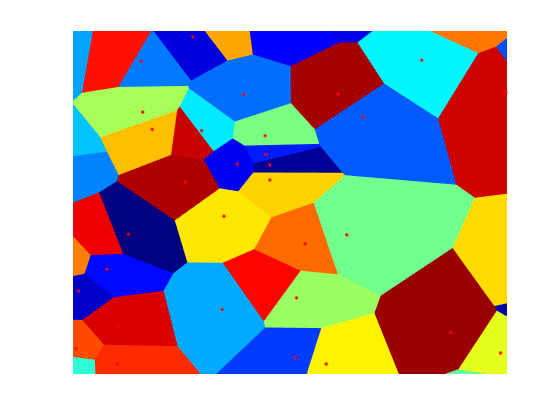

Centroid_X = map.centroid_x(Remaining_Centroid_Mask);
Centroid_Y = map.centroid_y(Remaining_Centroid_Mask);
plot(Centroid_X, Centroid_Y, 'r.');
hold off

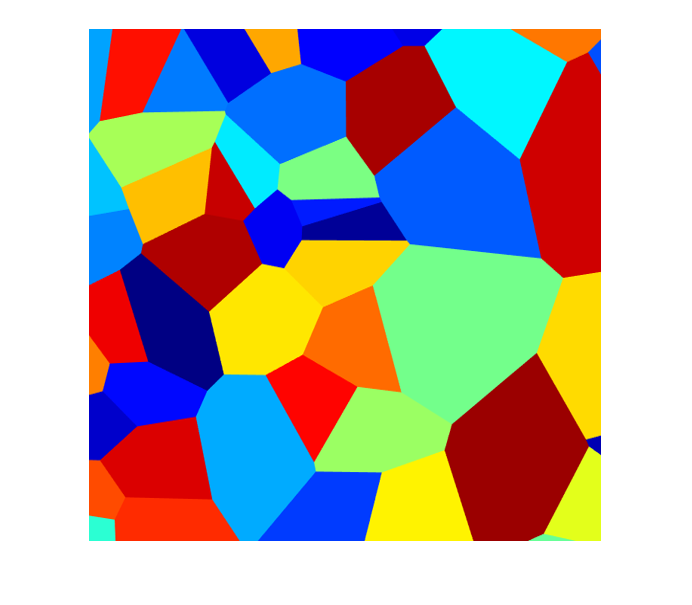

rgbImage = imread('voronoi.png');
rgbImage = CropFrame(rgbImage);

rgbImage = imresize(rgbImage, [512, 512]);
imwrite(rgbImage, 'voronoi.png')
imshow(rgbImage)

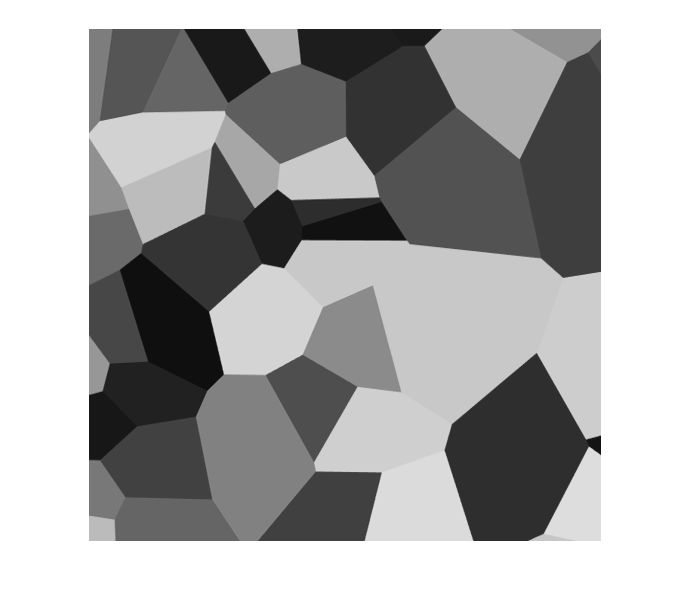

% VelocityData = rgbImage(:,:,1)/3 +rgbImage(:,:,2)/3+rgbImage(:,:,3)/3 ;
VelocityData = rgb2gray(rgbImage);
imshow(VelocityData)

[rows, columns, numberOfChannel] = size(VelocityData);
fprintf("[Info] Image resolution - row: %d column: %d ", rows, columns);

[Info] Image resolution - row: 512 column: 512 

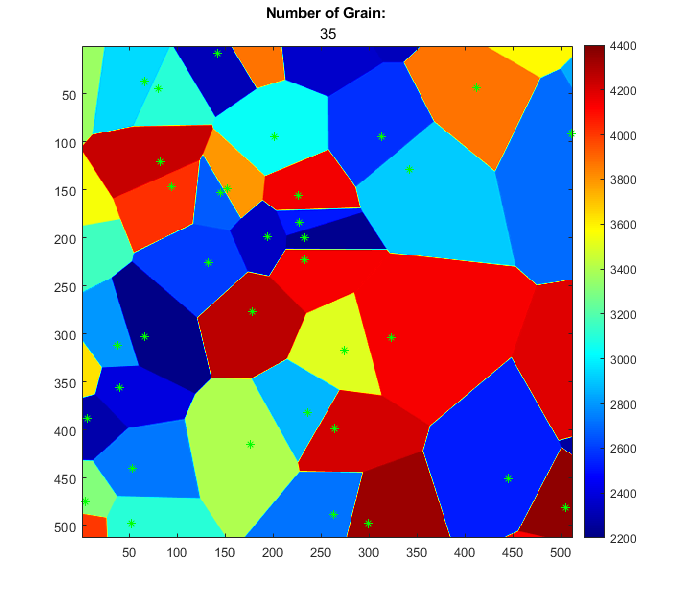


VelocityData = rescale(VelocityData, map.VelocityLower, map.VelocityUpper);
save("VoronoiData.mat", 'VelocityData');
Centroid_X = (Centroid_X-Trimming_Lower_limit)/(Trimming_Upper_Limit-Trimming_Lower_limit)*columns;
Centroid_Y = rows-(Centroid_Y-Trimming_Lower_limit)/(Trimming_Upper_Limit-Trimming_Lower_limit)*rows;
Velocity_map = imagesc(VelocityData);
axis off
saveas(Velocity_map,'voronoi.png');
axis on
colorbar;
title('Number of Grain: ',num2str(number_of_centroids(1)));
saveas(Velocity_map,'voronoi_report_only.png');

hold on;
plot(Centroid_X, Centroid_Y, 'g*');
hold off;
title('Number of Grain: ',num2str(number_of_centroids(1)));
saveas(Velocity_map,'centroids_report_only.png');
rgbImage = imread("voronoi.png");
rgbImage = CropFrame(rgbImage);
rgbImage = imresize(rgbImage, [512, 512]);
imwrite(rgbImage, 'voronoi.png')

hold off;

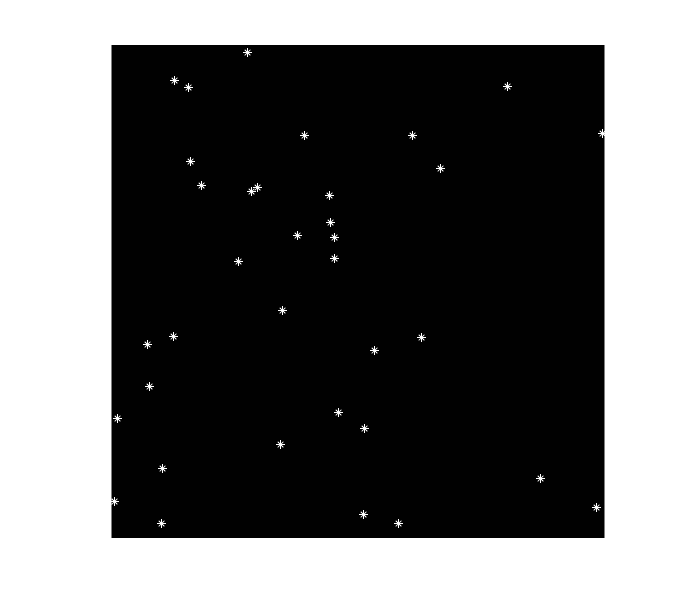


img=ones(512,512,3,'uint8');
imshow(img)
hold on;
plot(Centroid_X, Centroid_Y, 'w*');
Centroids_Coordinates = [Centroid_X'; Centroid_Y']';
save("Centroids_Coordinates.mat", 'Centroids_Coordinates');
axis off
saveas(gcf, 'RealCentroidsLocation', 'png');
hold off

centroidlocation = imread('RealCentroidsLocation.png');
centroidlocation = CropFrame(centroidlocation);
centroidlocation = imresize(centroidlocation,  [512, 512]);
imwrite(centroidlocation, 'RealCentroidsLocation.png');

